## ODE and PDE

### ODE

A system of **Ordinary Differential Equations (ODEs)** can be written in the form


$$\frac{dy}{dt}(t)=F(t,y)$$



$$y(0)=y_0$$


An ODE problem is **stiff** if the solution being sought is varying slowly, but there are nearby solutions that vary rapidly, so a numerical method must take small steps to obtain satisfactory results. Numerical schemes applied to stiff problems have very restrictive time steps for stability

**Various types of ODE solvers**

- Multi- vs single-stage

- Multi- vs single-step (Number of time steps used approximate time derivative)

- Implicit vs. Explicit (Trade-off between ease of advancing a single step versus number of steps required. Implicit schemes usually require solving a system of equations.)

- Serial vs. Parallel

#### Fourth-Order Explicit Runge-Kutta (ERK4)

A multi-stage, single-step, explicit, serial ODE solver.

Discretization of the time domain into $N+1$ intervals.

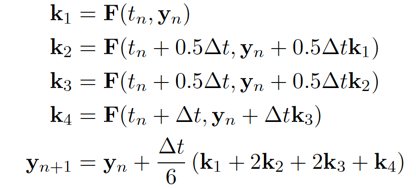

Fourth-order accuracy: error $\mathcal{O}(\Delta t^4)$

#### MATLAB ODE Solvers

`[TOUT,YOUT] = ode_solver(ODEFUN,TSPAN,Y0)`

`ODEFUN `is a function handle. 

- For a scalar T and a vector Y, `ODEFUN(T,Y) `must return a column vector corresponding to f(t,y)

`TSPAN = [T0 TFINAL]`

`Y0 `is the initial conditions 

Each row in the solution array `YOUT` corresponds to a time returned in the column vector `TOUT.`

Some options for `ode_solver`, its stiffness and accuracy:

- `ode45` Nonstiff, Medium

- `ode23` Nonstiff, Low

- `ode113` Nonstiff, Low - High

- `ode15s` Stiff, Low - Medium

- `ode23s` Stiff, Low

- `ode23t` Moderately stiff, Low

- `ode23tb` Stiff, Low

addpath('demo/')

**Demo**

Solve the simplified combustion model 

$y\prime \left(t\right)=y^2 \left(1-y\right)$, $0\le t\le \frac{2}{\epsilon },y\left(0\right)=\epsilon$ 

using `ode45` and `ode23s` with $\epsilon ={10}^{-4} ,{10}^{-3} ,{10}^{-2} ,{10}^{-1} ,1$.

ODE45 Timesteps for eps = 1.000000: 41


ODE23s Timesteps for eps = 1.000000: 11


ODE45 Timesteps for eps = 0.100000: 45


ODE23s Timesteps for eps = 0.100000: 21


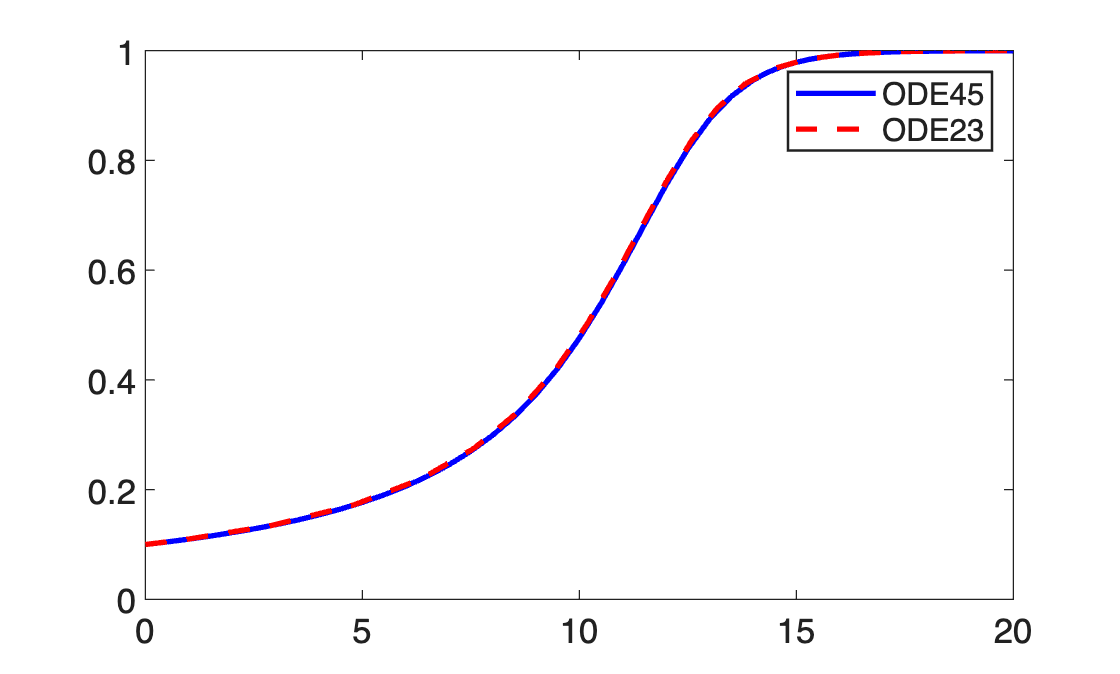

ODE45 Timesteps for eps = 0.010000: 157


ODE23s Timesteps for eps = 0.010000: 36


ODE45 Timesteps for eps = 0.001000: 1257


ODE23s Timesteps for eps = 0.001000: 47


ODE45 Timesteps for eps = 0.000100: 12113


ODE23s Timesteps for eps = 0.000100: 56


% ODE solvers
eps = [1, 1e-1 1e-2 1e-3 1e-4];
%eps = 1e-4;
f = @(t,y) y^2*(1-y);
for i = 1:length(eps)
    [t45,y45]  = ode45(f,[0,2/eps(i)],eps(i));
    [t23s,y23s] = ode23s(f,[0,2/eps(i)],eps(i));
    fprintf('ODE45 Timesteps for eps = %f: %d\n', eps(i),length(t45))
    fprintf('ODE23s Timesteps for eps = %f: %d\n', eps(i),length(t23s))
    if (eps(i) == 1e-1)
        plot(t45,y45,'b-', t23s, y23s, 'r--');
        legend('ODE45', 'ODE23')
    end
end

### PDE (partial differential equation)

The function being solved for depends on several variables, and the differential equation can include partial derivatives taken with respect to each of the variables.

Partial Differential Equations are ubiquitous in science and engineering. Some examples are

- Fluid Mechanics: Euler equations, Navier-Stokes equations

- Solid Mechanics: Structural dynamics

- Electrodynamics: Maxwell equations

- Quantum Mechanics: Schrodinger equation

Analytical solutions over arbitrary domains are mostly unavailable.

#### Classification of PDEs

**hyperbolic**:

- Ex: wave equation $\frac{\partial^2 u}{\partial t^2} -c^2 \frac{\partial^2 u}{\partial x^2}=0$

- Hyperbolic equations model the transport of some physical quantity, such as fluids or waves. 

**parabolic**:

- Ex: heat equation $\frac{\partial u}{\partial t} = \frac{\partial^2 u}{\partial x^2}$

- Parabolic problems describe evolutionary phenomena that lead to a steady state described by an elliptic equation. 

**elliptic**:

- Equations without a time derivative. 

- Ex: Laplace equation $\frac{\partial^2 u}{\partial x^2}=0$

- Elliptic equations are associated to a special state of a system, in principle corresponding to the minimum of the energy.

#### **Numerical Methods for solving PDEs**

- Finite Difference (FD)

- Finite Element (FE)

- Finite Volume (FV)

- Spectral (Fourier, Chebyshev)

- Discontinuous Galerkin (DG)

The (major) steps required to compute the numerical solution of to a system of Partial Differential Equations are

- Derive discretization of governing equations (Semi-discretization; Space-time discretization; Boundary conditions)

- Construct spatial mesh (or space-time mesh)

- If semi-discretized, define temporal mesh

- Implement and solve

- Postprocess

#### 1-D PDE solver in MATLAB

$u(x,t)$ that depends on time *t* and one spatial variable x

`sol = ``pdepe``(m,pdefun,icfun,bcfun,xmesh,tspan) `solves 1-D parabolic and elliptic PDEs

- `m` is the symmetry constant.

- `pdefun` defines the equations being solved.

- `icfun` defines the initial conditions.

- `bcfun` defines the boundary conditions.

- `xmesh` is a vector of spatial values for *x*.

- `tspan` is a vector of time values for *t*.

- `sol` is a 3-D solution array. `ui` = `sol`(`:`,`:`,`i`) is an approximation to the `i`th component of the solution vector $u$. The element `ui`(`j`,`k`) = `sol`(`j`,`k`,`i`) approximates $u_i$ at (*t*,*x*) = (`tspan`(`j`),`xmesh`(`k`)).

The **standard form** that `pdepe` expects is


$$c\left(x,t,u,\frac{\partial u}{\partial x}\right)\frac{\partial u}{\partial t}=x-m\frac{\partial }{\partial x}\left(x^m f\left(x,t,u,\frac{\partial u}{\partial x}\right)\right)+s\left(x,t,u,\frac{\partial u}{\partial x}\right)$$


The initial condition function should have signature `u0 = pde_ic(x).` 

The standard form for the boundary conditions expected by the solver is


$$p\left(x,t,u\right)+q\left(x,t\right)f\left(x,t,u,\frac{\partial u}{\partial x}\right)=0$$


and use the function signature `[pl,ql,pr,qr] = pde_bc(xl,ul,xr,ur,t).`

**Demo**:  solve $\pi^2\frac{\partial u}{\partial t} = \frac{\partial^2 u}{\partial x^2}$ with initial condition $u(x,0)=\sin(\pi x)$ and boundary conditions $u(0,t)=0, \pi e^{-t}+\frac{\partial u}{\partial x}(1,t)=0$.

- code the equation: $\pi^2 \frac{\partial u}{\partial t}=x^0 \frac{\partial }{\partial x}\left(x^0 \frac{\partial u}{\partial x}\right)+0$ 

- code the initial conditions 

- code the boundary conditions: $u+0\cdot \frac{\partial u}{\partial x}=0,\pi e^{-t} +1\cdot \frac{\partial u}{\partial x}\left(1,t\right)=0$ 

- select a suitable solution mesh 

- call the solver `pdepe`

`pde1d_demo.m`

Example of solving a system of PDEs: [https://www.mathworks.com/help/matlab/math/solve-system-of-pdes.html](https://www.mathworks.com/help/matlab/math/solve-system-of-pdes.html) 

#### Partial Differential Equation Toolbox for General PDEs

A typical workflow for solving a general PDE or a system of PDEs includes the following steps:

- Convert PDEs to the form required by the toolbox.

- Create a PDE model container specifying the number of equations.

- Define 2-D or 3-D geometry and mesh it using triangular and tetrahedral elements with linear or quadratic basis functions.

- Specify the coefficients, boundary and initial conditions. 

- Solve and plot the results at nodal locations or interpolate them to custom locations.

**Geometry Definition**

Construct mesh interactively using pdetool

- Unions and intersections of basic shapes: Rectangles, ellipses, circles, etc

Use `pdegeom` to create geometry programmatically

- Build parametrized, oriented boundary edges

- Label left and right regions of edges

- Geometry built from union of regions with similar labels

**Mesh Generation**

- `initmesh` Create initial triangular mesh

- `adaptmesh `Adaptive mesh generation and PDE solution

- `jigglemesh` Jiggle internal points of triangular mesh

- `reinemesh` Refine triangular mesh

- `tri2grid `Interpolate from PDE triangular mesh to rectangular grid

- `pdemesh` Plot PDE triangular mesh

- `pdetriq` Triangle quality measure

**Demo**

The NACA airfoils are airfoil shapes for aircraft wings developed by the National Advisory Committee for Aeronautics (NACA).

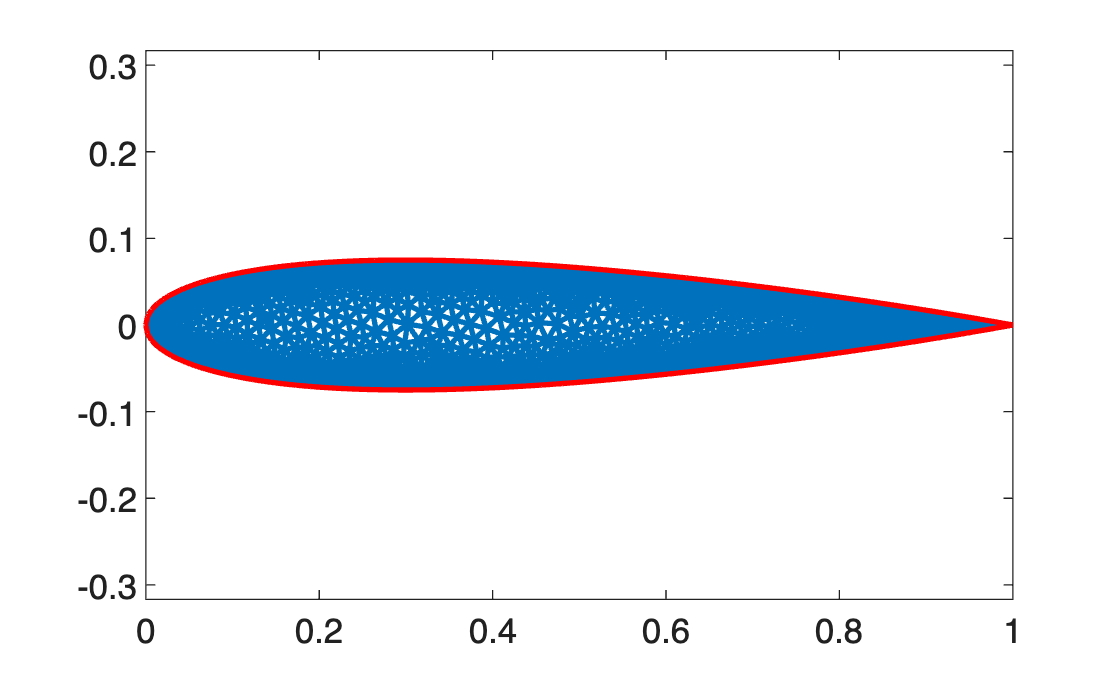

[p,e,t]=initmesh('naca');
pdemesh(p,e,t), axis equal

**Problem Definition**

Both scalar and vector PDEs are available in PDE toolbox.

Here we focus on **scalar PDEs**.

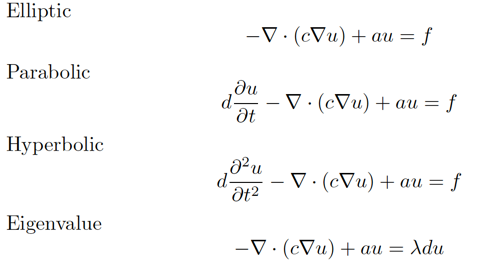

PDE coefficients $a,c,d,f$ can vary with space and time (can also depend on the solution $u$ or the edge segment index)

**Boundary conditions** are available for both scalar and vector available in PDE toolbox.

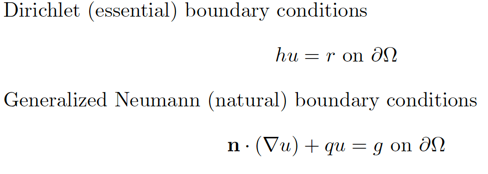

Boundary coefficients $h,r,q,g$ can vary with space and time (can also depend on the solution $u$ or the edge segment index)

**Specify Boundary Conditions**

Boundary conditions can be specified:

- Graphically using `pdetool`

- Programmatically using `pdebound: [q,g,h,r] = pdebound(p,e,u,time)`

**Specify PDE Coeffcients**

PDE coeffcients can be specified:

- Graphically using `pdetool`

- Programmatically via constants, strings, functions: `u = parabolic(u0,tlist,b,p,e,t,c,a,f,d);`

**PDE solvers**

- Elliptic: `[u,res]=pdenonlin(b,p,e,t,c,a,f);`

- Parabolic: `u=parabolic(u0,tlist,b,p,e,t,c,a,f,d);`

- Hyperbolic: `u=hyperbolic(u0,ut0,tlist,b,p,e,t,c,a,f,d);`

`result = ``solvepde``(model``) `solves a stationary PDE defined by the PDEModel `model` and returns the `result` in a StationaryResults object.

**Demo**

u=parabolic(0,linspace(0,0.1,200),@nacabound,p,e,t,1,0,0,1);

220 successful steps
0 failed attempts
439 function evaluations
1 partial derivatives
36 LU decompositions
438 solutions of linear systems


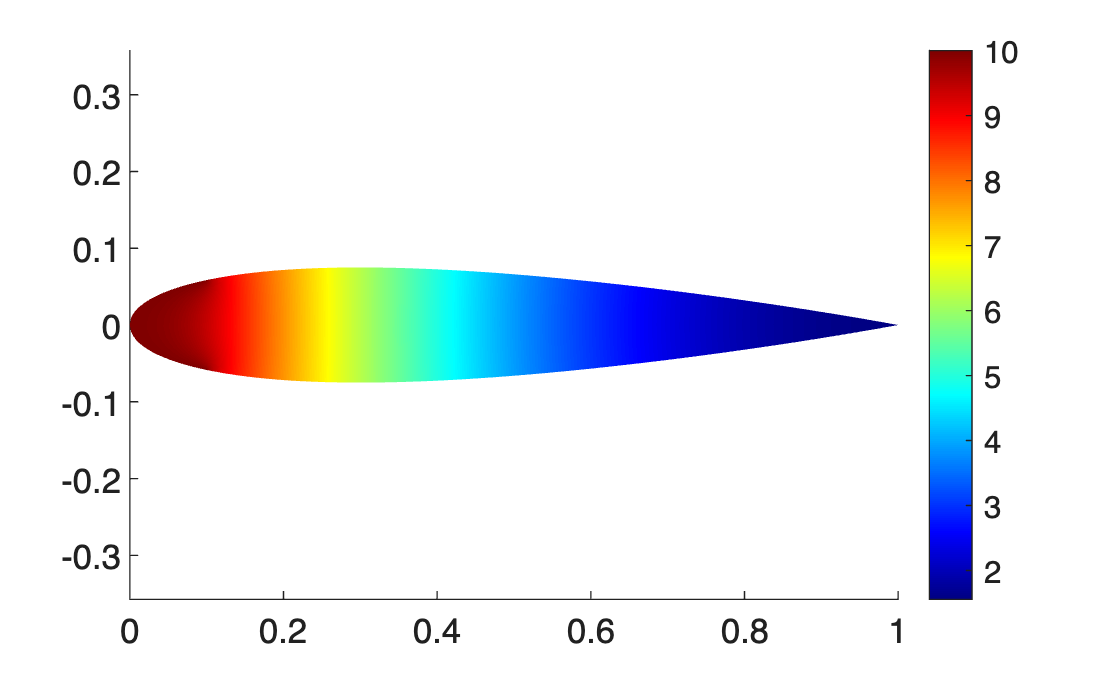

pdeplot(p,e,t,'xydata',u(:,end),'colormap','jet'); axis equal;

addpath(pwd);   % if load_house_uv_sample.m is in same folder

function D = load_house_uv_sample(matfile, k, opts)
%LOAD_HOUSE_UV_SAMPLE Load one sample from a channel-first "house format" MAT file.
%
% Expected MAT contents:
%   X_data: [N, Cx, Ny, Nx]
%   Y_data: [N, Cy, Ny, Nx]
% Optional:
%   x: [1,Nx] or [Nx,1]
%   y: [1,Ny] or [Ny,1]
%   mask: [Ny,Nx] or [1,Ny,Nx] or [Ny,Nx,1]
%
% Usage:
%   D = load_house_uv_sample("ns2d_fno_pretrained_export.mat", 1);
%   imagesc(D.x, D.y, D.speed_pred); set(gca,"YDir","normal"); axis image
%
% opts fields (all optional):
%   opts.u_in_chan   (default 2)  -> X_data channel for u0
%   opts.v_in_chan   (default 3)  -> X_data channel for v0
%   opts.u_out_chan  (default 1)  -> Y_data channel for u1/pred
%   opts.v_out_chan  (default 2)  -> Y_data channel for v1/pred
%   opts.omega_in_chan  (default 1)  -> X_data channel for omega0
%   opts.omega_out_chan (default 3)  -> Y_data channel for omega1/pred
%   opts.speed_out_chan (default 4)  -> Y_data channel for speed
%
% Returns struct D with:
%   D.u0, D.v0, D.omega0
%   D.u1, D.v1, D.omega1, D.speed1
%   D.x, D.y, D.mask
%   D.X (Cx x Ny x Nx), D.Y (Cy x Ny x Nx)
%
% Notes:
% - Uses 1-based indexing for channels (MATLAB).
% - Squeezes dims safely to get [Ny,Nx] fields.

    arguments
        matfile (1,:) char
        k (1,1) double {mustBeInteger, mustBePositive}
        opts.u_in_chan (1,1) double {mustBeInteger, mustBePositive} = 2
        opts.v_in_chan (1,1) double {mustBeInteger, mustBePositive} = 3
        opts.u_out_chan (1,1) double {mustBeInteger, mustBePositive} = 1
        opts.v_out_chan (1,1) double {mustBeInteger, mustBePositive} = 2
        opts.omega_in_chan (1,1) double {mustBeInteger, mustBePositive} = 1
        opts.omega_out_chan (1,1) double {mustBeInteger, mustBePositive} = 3
        opts.speed_out_chan (1,1) double {mustBeInteger, mustBePositive} = 4
    end

    S = load(matfile);

    assert(isfield(S,"X_data") && isfield(S,"Y_data"), ...
        "MAT file must contain X_data and Y_data (channel-first).");

    X_data = S.X_data;  % N x Cx x Ny x Nx
    Y_data = S.Y_data;  % N x Cy x Ny x Nx

    assert(ndims(X_data) == 4 && ndims(Y_data) == 4, ...
        "X_data and Y_data must be 4D arrays: [N,C,Ny,Nx].");

    N = size(X_data, 1);
    assert(k >= 1 && k <= N, "k must be in [1,%d]", N);

    Cx = size(X_data, 2);
    Cy = size(Y_data, 2);

    assert(opts.u_in_chan <= Cx && opts.v_in_chan <= Cx && opts.omega_in_chan <= Cx, ...
        "Input channel index exceeds X_data channels (Cx=%d).", Cx);
    assert(opts.u_out_chan <= Cy && opts.v_out_chan <= Cy && opts.omega_out_chan <= Cy, ...
        "Output channel index exceeds Y_data channels (Cy=%d).", Cy);

    % Pull full channel stacks for this sample: [C x Ny x Nx]
    X = squeeze(X_data(k, :, :, :));
    Y = squeeze(Y_data(k, :, :, :));

    % Ensure shape is [C,Ny,Nx]
    if ndims(X) ~= 3
        error("Unexpected X shape after squeeze: %s", mat2str(size(X)));
    end
    if ndims(Y) ~= 3
        error("Unexpected Y shape after squeeze: %s", mat2str(size(Y)));
    end

    % Extract key fields
    omega0 = squeeze(X(opts.omega_in_chan, :, :));
    u0     = squeeze(X(opts.u_in_chan, :, :));
    v0     = squeeze(X(opts.v_in_chan, :, :));

    omega1 = squeeze(Y(opts.omega_out_chan, :, :));
    u1     = squeeze(Y(opts.u_out_chan, :, :));
    v1     = squeeze(Y(opts.v_out_chan, :, :));

    speed1 = [];
    if opts.speed_out_chan <= Cy
        speed1 = squeeze(Y(opts.speed_out_chan, :, :));
    end

    % Load x,y if present; otherwise default to unit square grid
    Ny = size(u0,1); Nx = size(u0,2);
    if isfield(S,"x"), x = S.x(:)'; else, x = linspace(0,1,Nx); end
    if isfield(S,"y"), y = S.y(:)'; else, y = linspace(0,1,Ny); end

    % Load mask if present
    if isfield(S,"mask")
        mask = S.mask;
        mask = squeeze(mask);
        if ~isequal(size(mask), [Ny, Nx])
            error("mask has size %s but expected [%d %d].", mat2str(size(mask)), Ny, Nx);
        end
        mask = logical(mask);
    else
        mask = true(Ny, Nx);
    end

    % Package output
    D = struct();
    D.X = X;
    D.Y = Y;

    D.x = x;
    D.y = y;
    D.mask = mask;

    D.omega0 = omega0;
    D.u0 = u0;
    D.v0 = v0;

    D.omega1 = omega1;
    D.u1 = u1;
    D.v1 = v1;
    D.speed1 = speed1;
end

%% ===== Dataset config (HOUSE FORMAT) =====
% Choose ONE:
%   "ns2d_fno_pretrained_export.mat"   (classic FNO vorticity -> u,v export)
%   "pdebench_export.mat"              (your PDEBench->MAT converter output)

MATFILE = "ns2d_pretrained_outputs/ns2d_fno_pretrained_export.mat";
% MATFILE = "pdebench_export.mat";

k = 1;                 % sample index

% Boundary type for derived PDE steps:
% - classic NS2D periodic box: "periodic"
% - many PDEBench grids: "dirichlet" (reasonable default for class demos)
BC_TYPE = "periodic";
% BC_TYPE = "dirichlet";


## PDE Demo 1: Visualization + PDE diagnostics (divergence-free + vorticity)

A raw velocity snapshot becomes substantially more informative once it is treated as a discretized vector field u(x, y), v(x, y) and interrogated with the differential operators that appear in the governing equations. 

Core ideas:

- Numerical differentiation on a grid (via `gradient`) and the role of spacing (Delta x, Delta y).

- Incompressibility as a constraint

What the results show:

- The velocity visualization reveal a coherent flow structure. 

- Discretization error, interpolation artifacts (if the field is model output), and boundary stencils typically produce visible edge effects.

- The vorticity plot concentrated where the flow has shear: near moving boundaries, in boundary layers, and around sharp turns. 

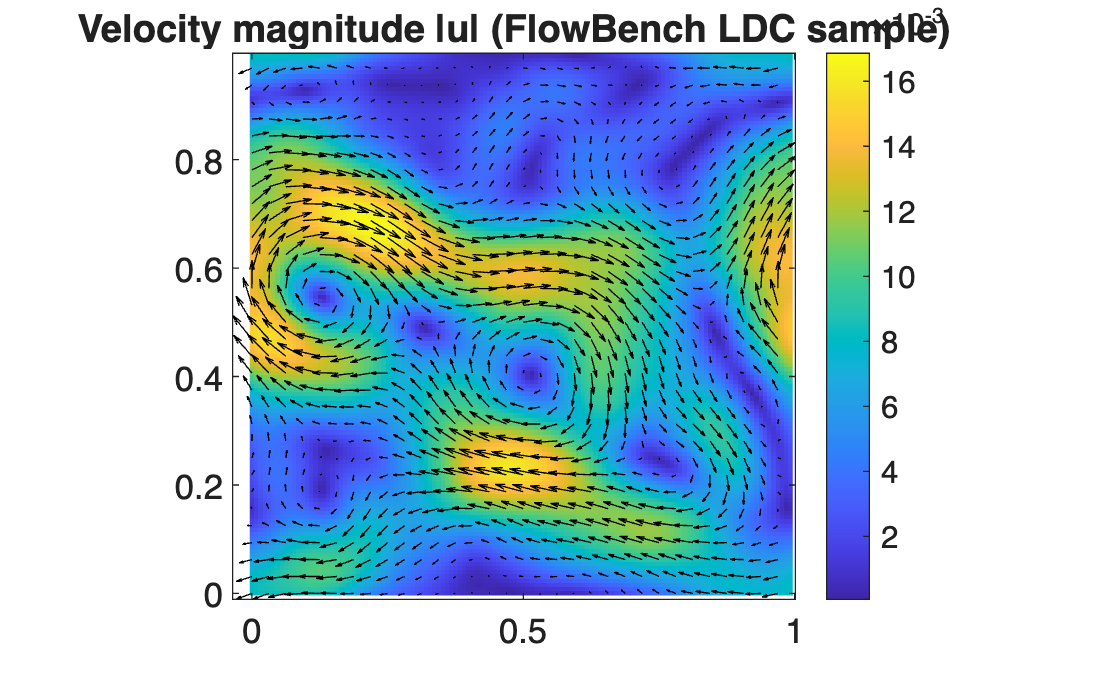

D = load_house_uv_sample(MATFILE, k);
u = D.u1; v = D.v1;
x = D.x;  y = D.y;
mask = D.mask;
Ny = size(u,1); Nx = size(u,2);


% Derivatives (gradient returns [d/dy, d/dx] for matrices)
[dudy, dudx] = gradient(u, y, x);
[dvdy, dvdx] = gradient(v, y, x);

divU  = dudx + dvdy;
omega = D.omega1; 

% Remove boundary artifacts (set to NaN so they don't dominate color scaling)
divU([1 end],:) = NaN; divU(:,[1 end]) = NaN;
omega([1 end],:) = NaN; omega(:,[1 end]) = NaN;

speed = hypot(u,v);

figure;
imagesc(x, y, speed); set(gca,"YDir","normal"); axis image; colorbar
title("Velocity magnitude |u| (FlowBench LDC sample)")
hold on
sx = 1:4:Nx; sy = 1:4:Ny;
quiver(x(sx), y(sy), u(sy,sx), v(sy,sx), 1.5, "k")


figure;
tiledlayout(1,2);

nexttile;
A = divU; A(~mask) = NaN;
cl = prctile(abs(A(~isnan(A))), 99);   % robust limit
imagesc(x, y, A); set(gca,"YDir","normal"); axis image; colorbar
clim([-cl cl]);
title(sprintf("Divergence gradient dot u (clipped at 99%% = %.2g)", cl))

nexttile;
B = omega; B(~mask) = NaN;
clw = prctile(abs(B(~isnan(B))), 99);
imagesc(x, y, B); set(gca,"YDir","normal"); axis image; colorbar
clim([-clw clw]);
title(sprintf("Vorticity omega (clipped at 99%% = %.2g)", clw))

div_rms = rms(A(~isnan(A)));
fprintf("RMS divergence (interior) = %.3e\n", div_rms);

RMS divergence (interior) = 6.868e-02


## PDE Demo 2: Solve a derived PDE: streamfunction Poisson equation

Stream function phi: given vorticity omega, recover phi by solving a Poisson equation. 

Core ideas:

- Elliptic PDEs (Poisson) and boundary conditions

- Discretization produces a sparse SPD system on interior nodes.

- Solver choice: FFT-based diagonalization for periodic boxes; iterative Krylov methods (PCG) with preconditioning for general masked domains.

What the results show:

- The recovered phi is smooth relative to omega, since Poisson inversion acts like a spatial low-pass filter (two derivatives “integrated back”). Fine-scale noise in omega gets attenuated in phi.

- Contours of phi align with streamlines of the velocity field. Overlaying velocity vectors on phi show the vectors tangent to phi-contours in the interior.

- The PCG diagnostics provide concrete numerical sanity check: if PCG stagnates or takes an extreme number of iterations, it usually indicates a poor preconditioner, a badly scaled grid spacing, or an inconsistency in the mask/BC handling.

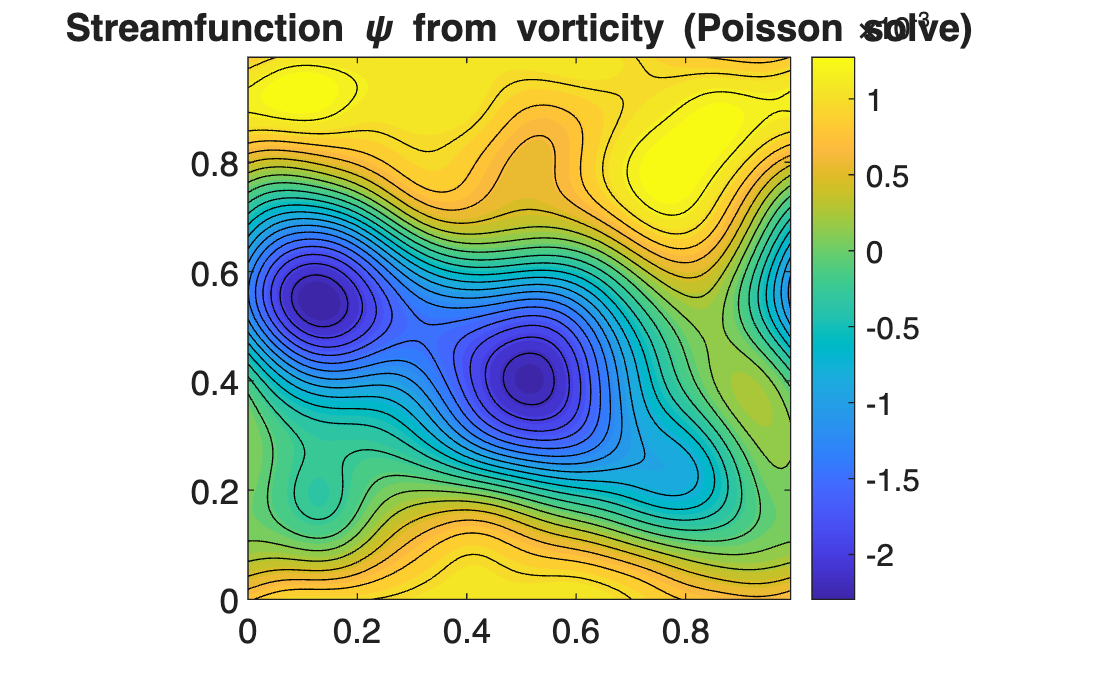

D = load_house_uv_sample(MATFILE, k);
u = D.u1; v = D.v1;
x = D.x;  y = D.y;
mask = D.mask;

Ny = size(u,1); Nx = size(u,2);

omega = D.omega1;
omega(~mask) = 0;

if BC_TYPE == "periodic"
    psi = poisson_periodic_fft(-omega, x, y); % solves Delta psi = -omega
else
    psi = poisson_dirichlet_pcg(-omega, x, y, mask); % solves Delta psi = -omega with psi=0 on boundary/solid
end

psi(~mask) = NaN;

figure;
contourf(x, y, psi, 35, "LineColor","none");
set(gca,"YDir","normal"); axis image; colorbar
title("Streamfunction \psi from vorticity (Poisson solve)")
hold on
contour(x, y, psi, 20, "k");

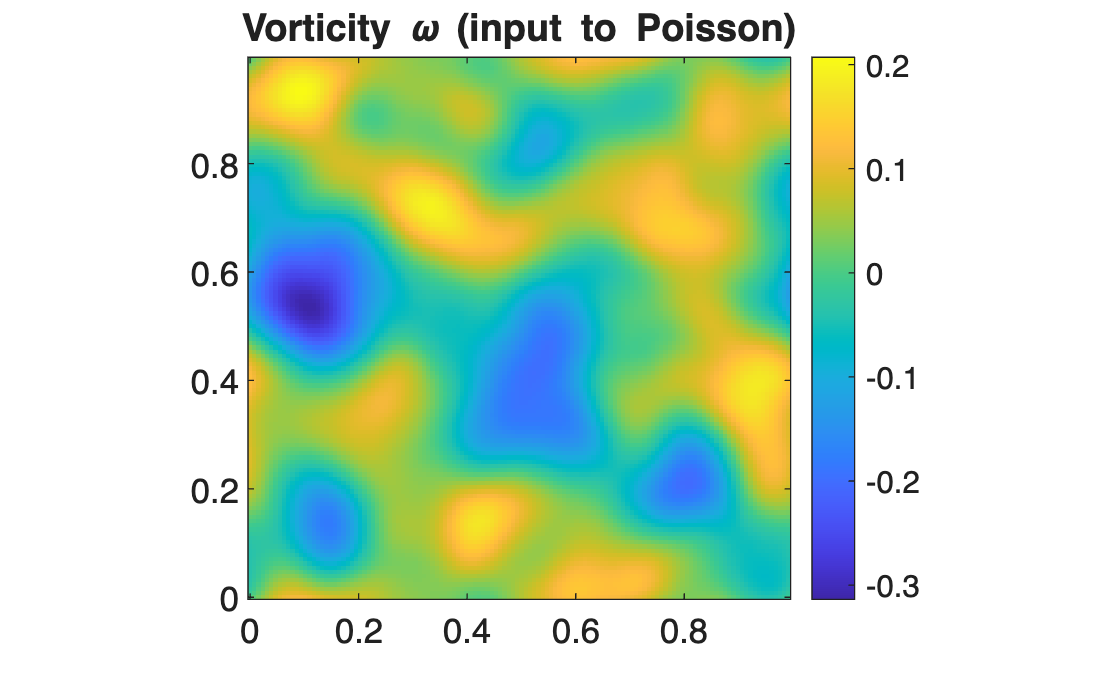

figure;
imagesc(x, y, omega); axis image; set(gca,"YDir","normal"); colorbar
title("Vorticity \omega (input to Poisson)")

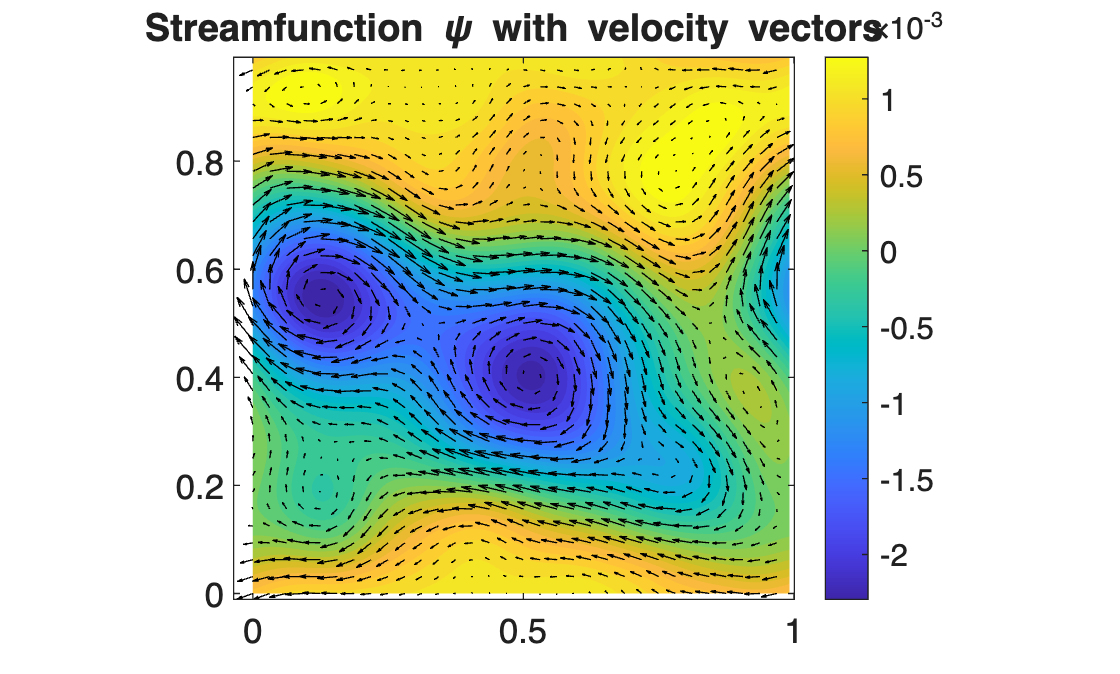


[Xg, Yg] = meshgrid(x, y);
ds = 4;

figure;
contourf(x, y, psi, 35, "LineColor","none");
set(gca,"YDir","normal"); axis image; colorbar
title("Streamfunction \psi with velocity vectors")
hold on
quiver(Xg(1:ds:end,1:ds:end), Yg(1:ds:end,1:ds:end), ...
       u(1:ds:end,1:ds:end), v(1:ds:end,1:ds:end), 1.5, "k");

## Demo 2B: Using MATLAB PDE Toolbox Instead

We can use PDE Toolbox instead to solve solve the PDE much faster and with less code. 

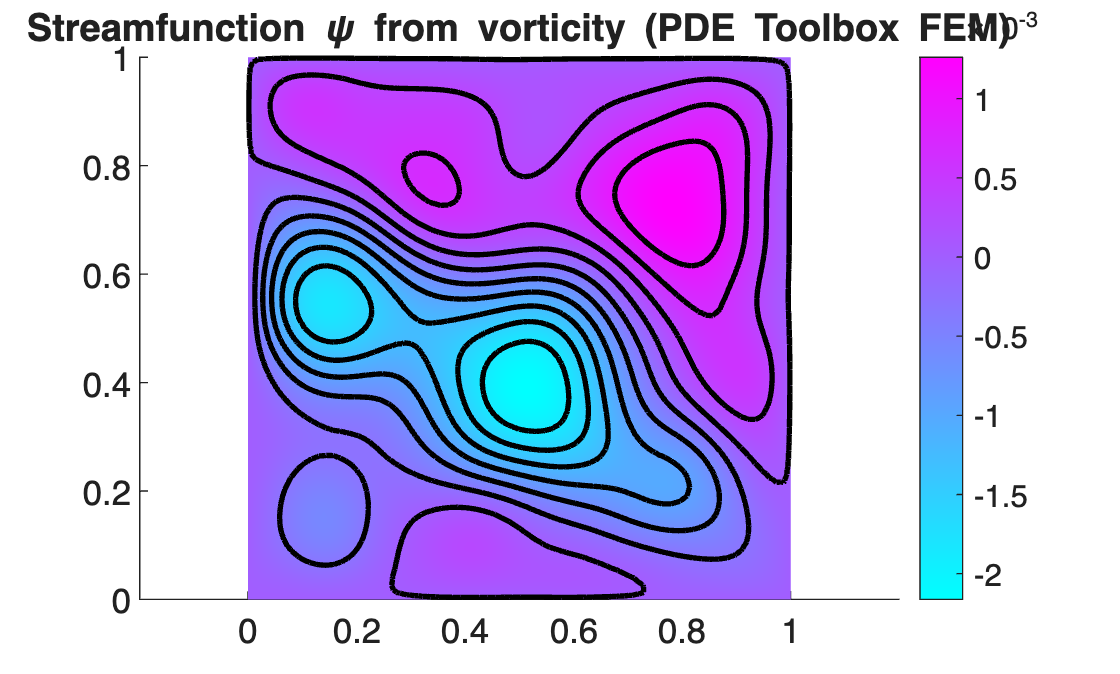

%% PDE Demo 2b (PDE Toolbox): FEM Poisson solve  -Delta psi = omega  on rectangle
% Requires PDE Toolbox

matPath = fullfile("ns2d_pretrained_outputs", "ns2d_fno_pretrained_export.mat");
k = 1;

D = load_house_uv_sample(matPath, k);
u = D.u1; v = D.v1;
x = D.x(:)';
y = D.y(:)';
mask = D.mask;

Ny = size(u,1); Nx = size(u,2);

omega = D.omega1;
omega(~mask) = 0;
omega(~isfinite(omega)) = 0;

x = double(x(:)');
y = double(y(:)');
omega = double(omega);

Fomega = griddedInterpolant({y, x}, omega, "linear", "nearest");

omegaFun = @(location, state) reshape( ...
    double(Fomega(location.y, location.x)), ...
    1, []);


% Build PDE model
model = createpde(1);

% Geometry bounds (cover full domain even if x(end)=Lx-dx)
dx = x(2) - x(1);
dy = y(2) - y(1);
xmin = x(1);
xmax = x(end) + dx;
ymin = y(1);
ymax = y(end) + dy;

R1 = [3,4, xmin, xmax, xmax, xmin, ymin, ymin, ymax, ymax]';
gd = R1; ns = char("R1")'; sf = "R1";
dl = decsg(gd, sf, ns);
geometryFromEdges(model, dl);

% Mesh
generateMesh(model, "Hmax", 0.03);

% Solve -Delta psi = omega  (PDE Toolbox form: -div(c grad u) + a u = f)
specifyCoefficients(model, "m",0, "d",0, "c",1, "a",0, "f", omegaFun);

% Simple boundary condition
applyBoundaryCondition(model, "dirichlet", "Edge", 1:model.Geometry.NumEdges, "u", 0);

% Solve
res = solvepde(model);
psiFEM = res.NodalSolution;

% Visualize FEM solution
figure;
pdeplot(model, "XYData", psiFEM, "Contour", "on");
axis equal
title("Streamfunction \psi from vorticity (PDE Toolbox FEM)")

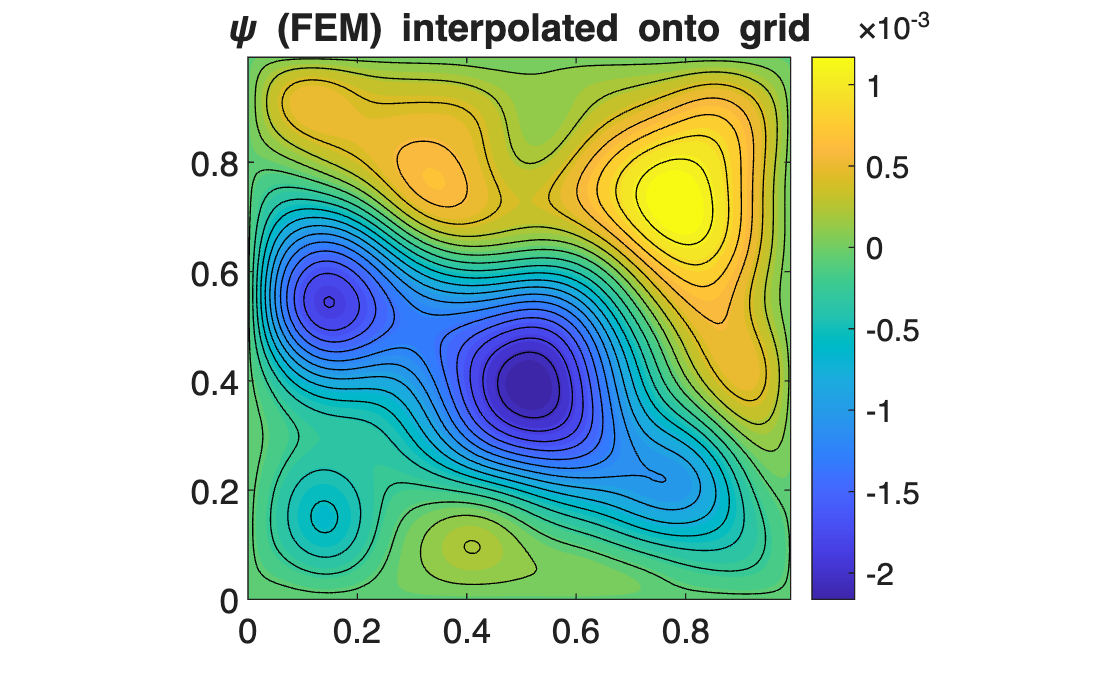


% Interpolate onto grid for consistent plotting with other demos
[Xg, Yg] = meshgrid(x, y);
psiGrid = interpolateSolution(res, Xg(:), Yg(:));
psiGrid = reshape(psiGrid, Ny, Nx);

psiGrid(~mask) = NaN;

figure;
contourf(x, y, psiGrid, 35, "LineColor","none"); colorbar; axis image
set(gca,"YDir","normal");
title("\psi (FEM) interpolated onto grid")
hold on; contour(x, y, psiGrid, 20, "k");

## PDE Demo 3: Advection–diffusion of a passive scalar (time stepping)

Here, we run a time-march on a transport PDE, using a real velocity field as the advecting flow. The scalar $c(x,y,t)$ can be interpreted as dye concentration, temperature, or any passive tracer. The point is twofold: (i) transport rapidly generates small scales (filaments) even from smooth initial conditions, and (ii) stability/accuracy constraints show up immediately, which is why numerical schemes and timestep selection matter.

Core ideas:

- Hyperbolic + parabolic structure

- Time stepping and CFL logic: even when the advection update is semi-Lagrangian (stable), timestep still controls accuracy (how well backtracing resolves deformation).

- Operator splitting in practice: semi-Lagrangian advection followed by an explicit diffusion step.

- Boundary handling and physical constraints: clamping to avoid negative concentrations from interpolation; enforcing walls/mask.

What the results show:

- Two initially localized blobs stretch into long, thin filaments along the flow, especially near high-shear regions.

- Over long enough time, the scalar approaches a mixed state (nearly uniform within the accessible fluid region, modulo boundary forcing). 

D = load_house_uv_sample(MATFILE, k);
u = D.u1; v = D.v1;
x = D.x;  y = D.y;
mask = D.mask;

Ny = size(u,1); Nx = size(u,2);
hx = x(2)-x(1); hy = y(2)-y(1);


[Xg, Yg] = meshgrid(x, y);

% Parameters
kappa  = 1e-5; % diffusion (smaller -> sharper filaments longer)
Tfinal = 300.0; % 30 is "fully mixed"; 4–10 is the wow window
CFL    = 0.9; % advection accuracy knob (semi-Lagrangian stable anyway)

% Blob size
sigma1 = 0.08;
sigma2 = 0.10;
amp1 = 1.0;
amp2 = 0.8;

% Blob placement
c = amp1 * exp(-((Xg-0.20).^2 + (Yg-0.90).^2)/(2*sigma1^2)) + ...
    amp2 * exp(-((Xg-0.80).^2 + (Yg-0.20).^2)/(2*sigma2^2));
c(~mask) = 0;

c0max = max(c(:)); % fixed color scale

umax = max(abs(u(mask)), [], "all");
vmax = max(abs(v(mask)), [], "all");

dt = CFL / (umax/hx + vmax/hy + 1e-12);
Nt = ceil(Tfinal/dt);
dt = Tfinal/Nt;

fprintf("dt = %.4g, Nt = %d, Tfinal = %.2f\n", dt, Nt, Tfinal);

dt = 0.2402, Nt = 1249, Tfinal = 300.00


fprintf("umax=%.3g, vmax=%.3g, kappa=%.2g\n", umax, vmax, kappa);

umax=0.0156, vmax=0.0136, kappa=1e-05


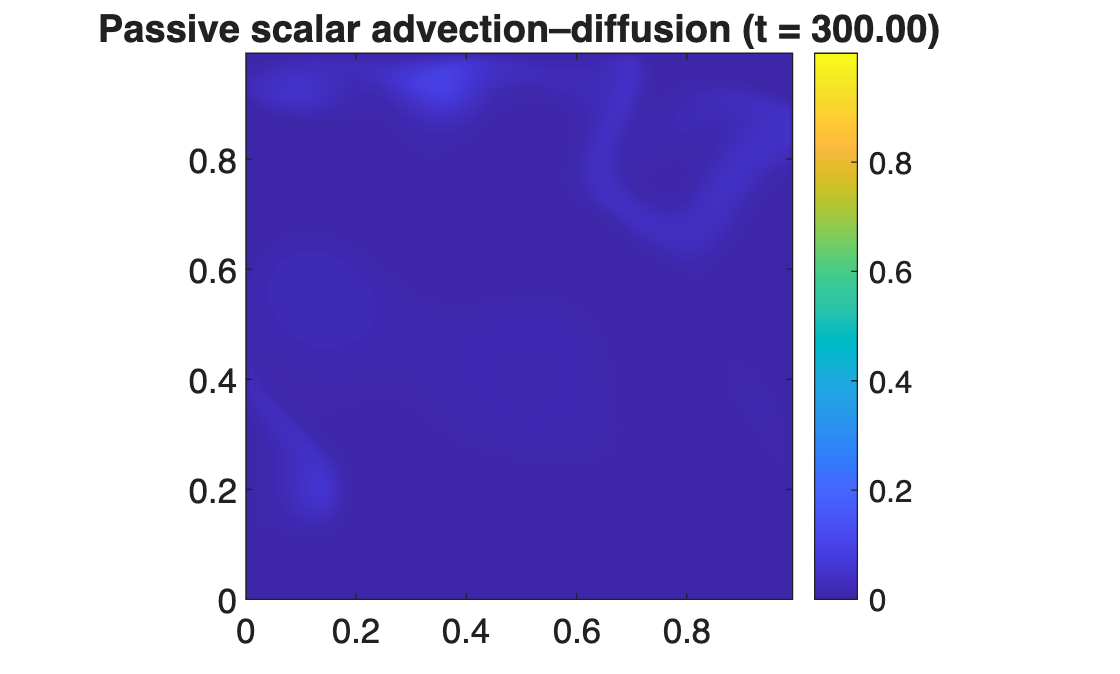


figure;

plotEvery = max(1, floor(Nt/120));

for n = 1:Nt
    c_old = c;

    Xb = Xg - dt*u;
    Yb = Yg - dt*v;

    % Clamp to domain
    Xb = min(max(Xb, x(1)), x(end));
    Yb = min(max(Yb, y(1)), y(end));

    % Interpolate
    c_adv = interp2(Xg, Yg, c_old, Xb, Yb, "cubic", 0);

    % Diffusion step (explicit central Laplacian)
    lap = zeros(Ny, Nx);
    ii = 2:Ny-1; jj = 2:Nx-1;
    lap(ii,jj) = (c_adv(ii, jj+1) - 2*c_adv(ii, jj) + c_adv(ii, jj-1))/hx^2 + ...
                 (c_adv(ii+1, jj) - 2*c_adv(ii, jj) + c_adv(ii-1, jj))/hy^2;

    c = c_adv + dt*kappa*lap;

    % Enforce walls (Dirichlet 0) + mask
    c([1 end],:) = 0; c(:,[1 end]) = 0;
    c(~mask) = 0;

    c = max(c, 0);

    if mod(n, plotEvery) == 0 || n == Nt
        contourf(x, y, c, 60, "LineColor", "none");
        set(gca, "YDir", "normal");
        axis image; colorbar;
        clim([0, c0max]);  
        title(sprintf("Passive scalar advection–diffusion (t = %.2f)", n*dt));
        drawnow;
    end
end


function psi = poisson_periodic_fft(rhs, x, y)
% Solve Delta psi = rhs on a periodic grid using FFT.

    Ny = size(rhs,1); Nx = size(rhs,2);
    Lx = x(end) - x(1) + (x(2)-x(1));
    Ly = y(end) - y(1) + (y(2)-y(1));

    kx = (2*pi/Lx) * [0:(Nx/2-1), -Nx/2:-1];
    ky = (2*pi/Ly) * [0:(Ny/2-1), -Ny/2:-1];
    [KX, KY] = meshgrid(kx, ky);
    K2 = KX.^2 + KY.^2;
    K2(1,1) = 1; % avoid divide by zero

    rhs_hat = fft2(rhs);
    psi_hat = rhs_hat ./ (-K2);
    psi_hat(1,1) = 0;
    psi = real(ifft2(psi_hat));
end

function psi = poisson_dirichlet_pcg(rhs, x, y, mask)
% Solve Delta psi = rhs with psi=0 on boundary + outside mask using sparse FD + PCG.
% Builds SPD system for (-Delta)psi = -rhs.

    Ny = size(rhs,1); Nx = size(rhs,2);
    hx = x(2)-x(1); hy = y(2)-y(1);

    unknown = mask;
    unknown([1 end],:) = false;
    unknown(:,[1 end]) = false;

    id = zeros(Ny,Nx);
    id(unknown) = 1:nnz(unknown);
    n = nnz(unknown);

    cx = 1/hx^2; cy = 1/hy^2;

    I = zeros(5*n,1); J = zeros(5*n,1); V = zeros(5*n,1); ptr = 0;

    for ii = 2:Ny-1
        for jj = 2:Nx-1
            if ~unknown(ii,jj), continue; end
            row = id(ii,jj);

            ptr=ptr+1; I(ptr)=row; J(ptr)=row; V(ptr)=2*cx+2*cy; % (-Δ) center

            if unknown(ii,jj-1), ptr=ptr+1; I(ptr)=row; J(ptr)=id(ii,jj-1); V(ptr)=-cx; end
            if unknown(ii,jj+1), ptr=ptr+1; I(ptr)=row; J(ptr)=id(ii,jj+1); V(ptr)=-cx; end
            if unknown(ii-1,jj), ptr=ptr+1; I(ptr)=row; J(ptr)=id(ii-1,jj); V(ptr)=-cy; end
            if unknown(ii+1,jj), ptr=ptr+1; I(ptr)=row; J(ptr)=id(ii+1,jj); V(ptr)=-cy; end
        end
    end

    A = sparse(I(1:ptr), J(1:ptr), V(1:ptr), n, n);

    b = -rhs(unknown);   % (-Delta)psi = -rhs

    setup.type = "ict"; setup.droptol = 1e-3;
    M = ichol(A, setup);
    [psi_vec, flag, relres, it] = pcg(A, b, 1e-8, 400, M, M');
    fprintf("PCG Poisson: flag=%d relres=%.2e it=%d\n", flag, relres, it);

    psi = zeros(Ny,Nx);
    psi(unknown) = psi_vec;
end


# In-Class Examples

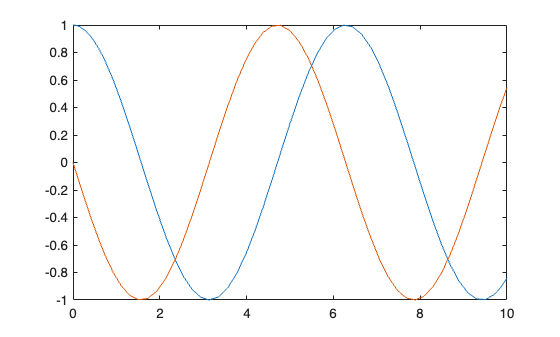

tspan = [0 10];
y0 = [1; 0];
[t,y] = ode45(@(t,y) [y(2); -y(1)], tspan, y0);
plot(t,y)

m = 0;
xmesh = linspace(0,1,50);
tspan = linspace(0,0.5,40);
sol = pdepe(m,@pdefun,@icfun,@bcfun,xmesh,tspan);

function [c,f,s] = pdefun(x,t,u,DuDx)
  c = 1; f = DuDx; s = 0;
end
function u0 = icfun(x)
  u0 = sin(pi*x);
end
function [pl,ql,pr,qr] = bcfun(xl,ul,xr,ur,t)
  pl = ul; ql = 0; pr = ur; qr = 0;
end

sol

sol =          0    0.0641    0.1279    0.1912    0.2537    0.3151    0.3753    0.4339    0.4907    0.5455    0.5981    0.6482    0.6957    0.7403    0.7818    0.8202    0.8551    0.8866    0.9144    0.9385    0.9587    0.9749    0.9872    0.9954    0.9995    0.9995    0.9954    0.9872    0.9749    0.9587    0.9385    0.9144    0.8866    0.8551    0.8202    0.7818    0.7403    0.6957    0.6482    0.5981    0.5455    0.4907    0.4339    0.3753    0.3151    0.2537    0.1912    0.1279    0.0641    0.0000
         0    0.0565    0.1127    0.1685    0.2236    0.2778    0.3308    0.3825    0.4326    0.4809    0.5272    0.5714    0.6132    0.6525    0.6892    0.7230    0.7538    0.7815    0.8060    0.8273    0.8451    0.8594    0.8702    0.8774    0.8810    0.8810    0.8774    0.8702    0.8594    0.8451    0.8273    0.8060    0.7815    0.7538    0.7230    0.6892    0.6525    0.6132    0.5714    0.5272    0.4809    0.4326    0.3825    0.3308    0.2778    0.2236    0.1685    0.1127    0.0565   